run('BASIC.m')
Question_mark='Q1';
tfinal=100;
[uc,t,Status,tfinal,Noix]=Datagen(0,T_s,tfinal,5,0,[0 0 0]);

Status = '-No NOISE-'

Titlework=[Question_mark,Status];

Am=poly([.8 .75])

Am =     1.0000   -1.5500    0.6000


Ao=poly([0])

Ao =      1     0


Ac=conv(Am,Ao);

Diophantine

[R , S ] = Diophantine(A , B , Ac)

R =     1.0000   -0.8000


S =     0.3000   -0.1700


N = numel(t) ;
u=zeros(N,1);
beta=sum(Am)/sum(B);
T=beta*Ao;

d=3

d = 3

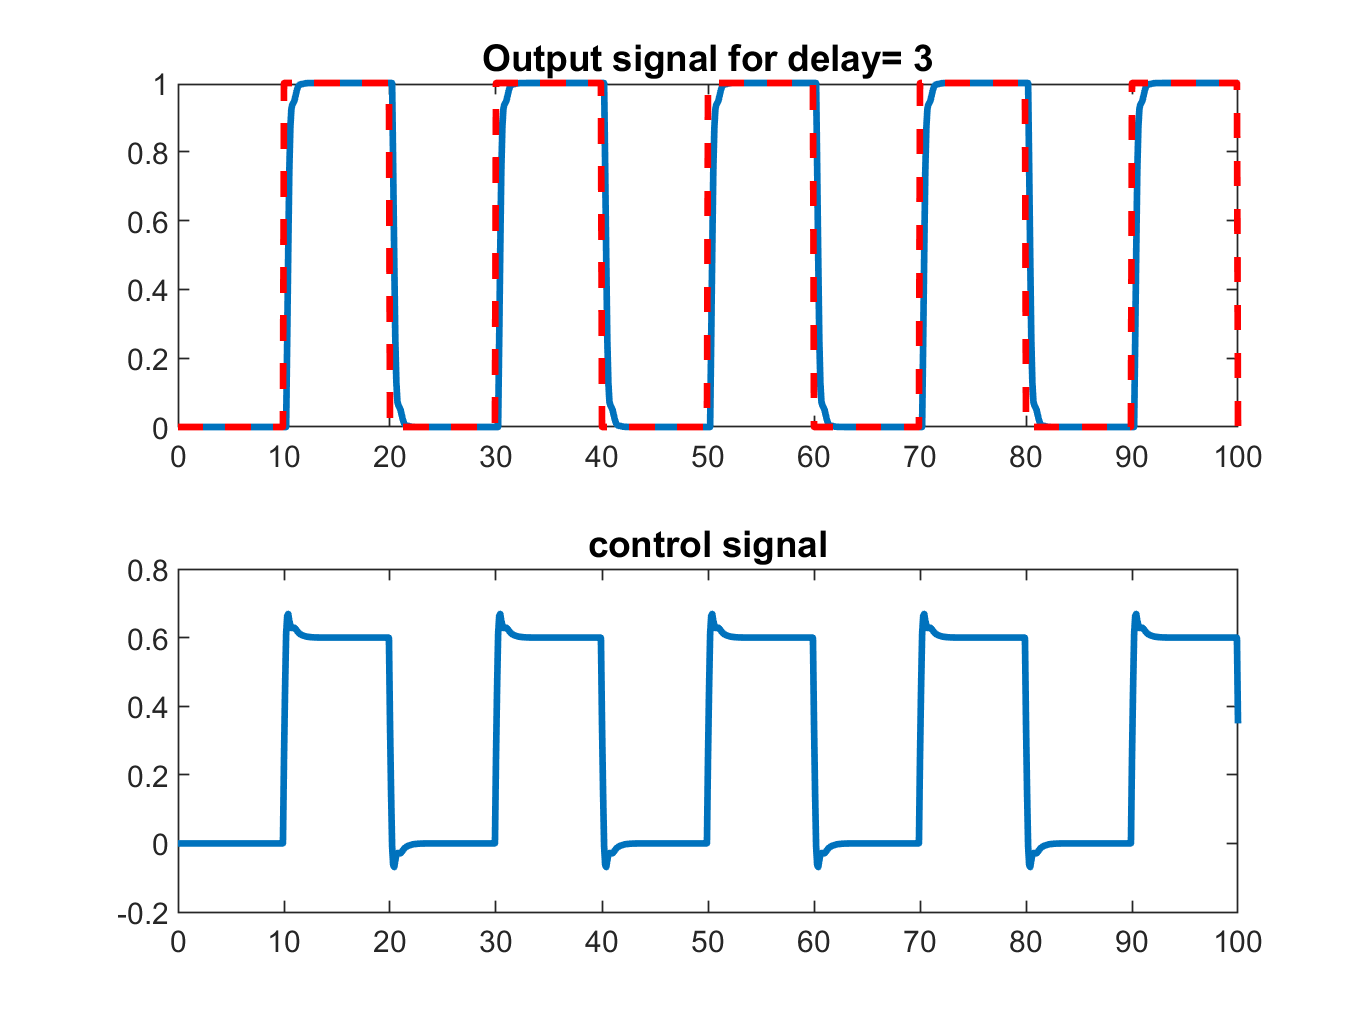

y(1:d+2)=0;
for i=d+3:N
    y(i)=-A(2:end)*y(i-1:-1:i-2)'+B*u(i-d:-1:i-d-1);
    u(i)=-(R(2:end)*u(i-1)+S*y(i:-1:i-1)')+T*uc(i:-1:i-1);
end

figure
subplot(2,1,1);
plot(t,y,'linewidth',2);
hold on;
plot(t,uc','--r','linewidth',2);
title(['Output signal for delay= ',int2str(d)],'fontsize',11)

subplot(2,1,2);
plot(t,u','linewidth',2);
title('control signal','fontsize',11);

print(gcf,[Titlework , num2str(plot_counter) , ' d=' num2str(d) ' Result.png'],'-dpng','-r400');

plot_counter=plot_counter+1;
